% %清空变量
warning off
close all
clear,clc

% 读取数据
data_allp = xlsread('D:\桌面\论文材料\RAMAN第二次实验\第三次过程光谱拟合标签.xlsx');
x = data_allp(:,6:end);


% 检测和处理异常值
mean_x = mean(x, 1);
std_x = std(x, 0, 1);
x_baseline_clean = x;
for i = 1:size(x, 2)
    idx = find(x(:,i) > mean_x(i) + 3 * std_x(i) |x(:,i) < mean_x(i) - 3 * std_x(i));
    x_baseline_clean(idx, i) = NaN;
end
for i = 1:size(x, 2)
    if any(isnan(x_baseline_clean(:,i)))
        x_baseline_clean(:,i) = fillmissing(x_baseline_clean(:,i), 'linear', 'EndValues', 'nearest');
    end
end

% Savitzky-Golay滤波
x_sg = sgolayfilt(x_baseline_clean', 11, 51)';
% SNV
x_svn = snv(x_sg);
% airpls 基线校正
[x_baseline, ~] = airPLS(x_svn, 10e5, 2, 0.1, 0.5, 20);
% 归一化
x_baseline = x_baseline ./ max(x_baseline, [], 'all');

load('SVR_model_glu.mat');
% 预测葡萄糖浓度
ypred_glu = predict(model, x_baseline);
for i = 1:length(ypred_glu)
    if ypred_glu(i) < 0
        ypred_gl(i) = 0;
    end
end
p_glu = polyfit(1:length(ypred_glu), ypred_glu', 3);
ypred_poly_glu = polyval(p_glu, 1:length(ypred_glu))';

% 加载模型
load('SVR_model_lac.mat');
% 预测乳酸浓度
ypred_lac = predict(model, x_baseline);
for i = 1:length(ypred_lac)
    if ypred_lac(i) < 0
        ypred_lac(i) = 0;
    end
end
p_lac = polyfit(1:length(ypred_lac), ypred_lac', 6);
ypred_poly_lac = polyval(p_lac, 1:length(ypred_lac))';

% 加载模型
load('SVR_model_Ammonium.mat');
% 预测铵离子浓度
ypred_amm = predict(model, x_baseline);
for i = 1:length(ypred_amm)
    if ypred_amm(i) < 0
        ypred_amm(i) = 0;
    end
end
p_amm = polyfit(1:length(ypred_amm), ypred_amm', 6);
ypred_poly_amm = polyval(p_amm, 1:length(ypred_amm))';

% 加载模型
load('SVR_model_OD600.mat');
% 预测OD600
ypred_OD = predict(model, x_baseline);
for i = 1:length(ypred_OD)
    if ypred_OD(i) < 0
        ypred_OD(i) = 0;
    end
end
p_OD = polyfit(1:length(ypred_OD), ypred_OD', 6);
ypred_poly_OD = polyval(p_OD, 1:length(ypred_OD))';

% 加载模型
load('SVR_model_protein.mat');
% 预测蛋白质浓度
ypred_pro = predict(model, x_baseline);
for i = 1:length(ypred_pro)
    if ypred_pro(i) < 0
        ypred_pro(i) = 0;
    end
end
p_pro = polyfit(1:length(ypred_pro), ypred_pro', 6);
ypred_poly_pro = polyval(p_pro, 1:length(ypred_pro))';

data_true = xlsread('D:\桌面\论文材料\RAMAN第二次实验\第三次检测值.xlsx');
x_true = data_true(:,1)

x_true =     26
    71
   100
   119
   150
   200
   230
   260
   270
   290


y1= data_true(:,2)

y1 =    16.0000
   12.3000
   12.0000
   11.0000
   10.0000
    8.0000
    7.3000
    5.2000
    3.9000
    2.3000


y2= data_true(:,3)

y2 =          0
         0
         0
         0
         0
         0
    0.0100
    0.0500
    0.0700
    0.1300


y3= data_true(:,4)

y3 =     80
    82
    84
    81
    80
    86
    91
    87
    81
    79


y4= data_true(:,5)

y4 =    34.0000
   35.0000
   35.3000
   40.0000
   41.0000
   70.0000
   90.0000
  110.0000
  112.0000
  117.0000


y5= data_true(:,6)

y5 =          0
         0
         0
         0
         0
         0
    0.1000
    0.2300
    0.4200
    0.8300


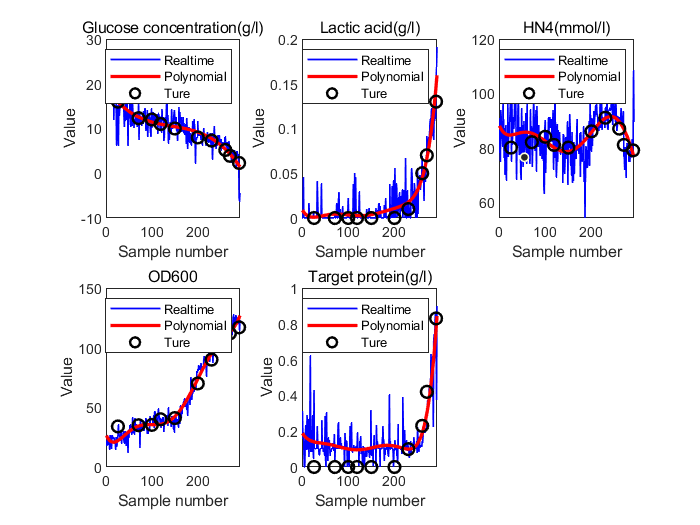

% 绘制子图
figure(1);
set(gcf, 'Color', 'w');
% 葡萄糖浓度
subplot(2,3,1);
plot(ypred_glu, '-b', 'LineWidth', 1);
hold on;
plot(ypred_poly_glu, '-r', 'LineWidth', 2);
hold on;
scatter(x_true, y1, 50, 'black', 'LineWidth', 1.5);
xlabel('Sample number');
ylabel('Value');
title(['Glucose concentration(g/l)']);
legend('Realtime', 'Polynomial','Ture');

% 乳酸浓度
subplot(2,3,2);
plot(ypred_lac, '-b', 'LineWidth', 1);
hold on;
plot(ypred_poly_lac, '-r', 'LineWidth', 2);
hold on;
scatter(x_true, y2, 50, 'black', 'LineWidth', 1.5);
xlabel('Sample number');
ylabel('Value');
title(['Lactic acid(g/l)']);
legend('Realtime', 'Polynomial','Ture');

% 铵离子浓度
subplot(2,3,3);
plot(ypred_amm, '-b', 'LineWidth', 1);
hold on;
plot(ypred_poly_amm, '-r', 'LineWidth', 2);
hold on;
scatter(x_true, y3, 50, 'black', 'LineWidth', 1.5);
xlabel('Sample number');
ylabel('Value');
title(['HN4(mmol/l)']);
legend('Realtime', 'Polynomial','Ture');

% od600
subplot(2,3,4);
plot(ypred_OD , '-b', 'LineWidth', 1);
hold on;
plot(ypred_poly_OD, '-r', 'LineWidth', 2);
hold on;
scatter(x_true, y4, 50, 'black', 'LineWidth', 1.5);
xlabel('Sample number');
ylabel('Value');
title(['OD600']);
legend('Realtime', 'Polynomial','Ture');


% 蛋白
subplot(2,3,5);
plot(ypred_pro , '-b', 'LineWidth', 1);
hold on;
plot(ypred_poly_pro, '-r', 'LineWidth', 2);
hold on;
scatter(x_true, y5, 50, 'black', 'LineWidth', 1.5);
xlabel('Sample number');
ylabel('Value');
title(['Target protein(g/l)']);
legend('Realtime', 'Polynomial','Ture');
hold off;